# Increase Overlap

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the signal and create a window.

load ./data/brokenouterrace.mat
winlen = n /5

winlen = 2400

w = kaiser(round(winlen), 19);

## Tasks

The number of samples to overlap can be set separately from the length of the window. For example, here are the segments when the window length is half of the signal, and the overlap is 50%:

numoverlap = round(0.5*winlen)

numoverlap = 1200

This code plots the spectrum. 

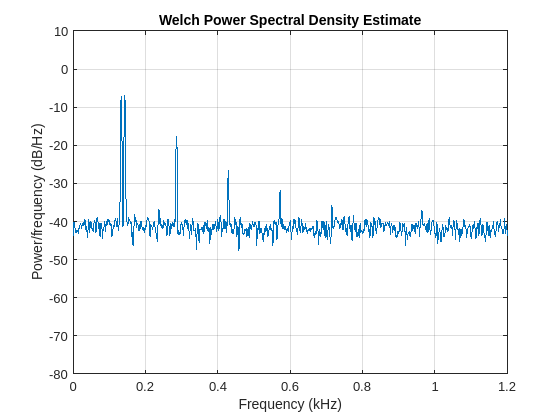

figure;
pwelch(sig, w, numoverlap, 2^12, fs);
ylim([-80 10])